**Task 3: Fourier transform (texture) – extension**

- **Result**: The result of the inverse Fourier transform should be the original image (or a close approximation). This is because the inverse Fourier transform reconstructs the image from its frequency components.

Difference Between Amplitude and Logarithm of Amplitude

- **Amplitude**: The amplitude of the Fourier transform represents the magnitude of the frequency components. It can have a wide range of values, making it difficult to visualize small details.

- **Logarithm of Amplitude**: Taking the logarithm of the amplitude compresses the range of values, making it easier to visualize both large and small details. This is especially useful for images with high dynamic range.

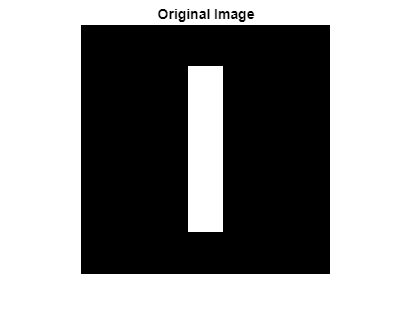

% Prepare image
f = zeros(256,256);
f(43:213,111:146) = 1;
imshow(f);
title('Original Image');


% Compute Fourier Transform
F = fft2(f,256,256);
figure;
imshow(F);

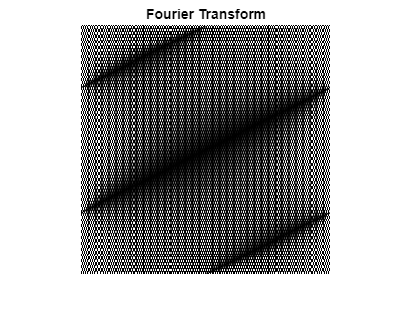

title('Fourier Transform');


F = fftshift(F); % Center FFT
figure;
imshow(F);

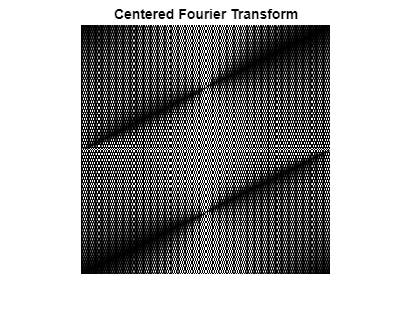

title('Centered Fourier Transform');


% Measure the minimum and maximum value of the transform amplitude
min_val = min(min(abs(F)));
max_val = max(max(abs(F)));
fprintf('Min amplitude: %f\n', min_val);

Min amplitude: 0.000000


fprintf('Max amplitude: %f\n', max_val);

Max amplitude: 6156.000000


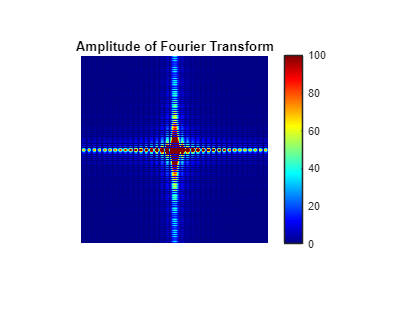


% Display the amplitude and its logarithm
figure;
imshow(abs(F), [0 100]);
colormap(jet);
colorbar;
title('Amplitude of Fourier Transform');

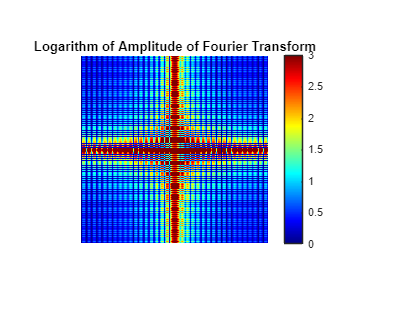


figure;
imshow(log(1+abs(F)), [0, 3]);
colormap(jet);
colorbar;
title('Logarithm of Amplitude of Fourier Transform');

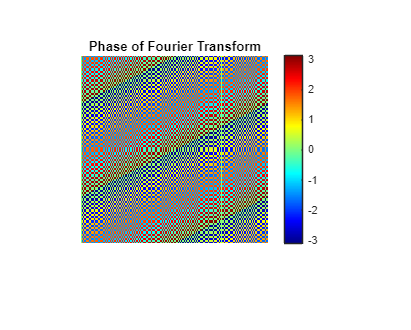


% Look at the phases
figure;
imshow(angle(F), [-pi, pi]);
colormap(jet);
colorbar;
title('Phase of Fourier Transform');

**Using Different Images**

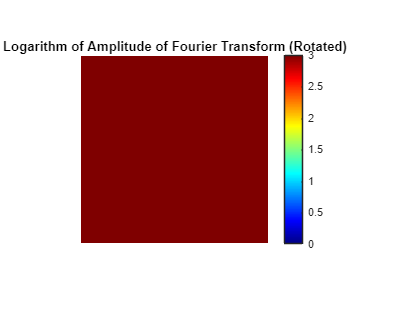

% Read and convert image to grayscale
f = imread('Test_1.tiff');
f = rgb2gray(f);
f = imresize(f, [256, 256]); % Resize if necessary

% Rotate the image
f_rotated = imrotate(f, 90); % Rotate by 90 degrees

% Compute Fourier Transform
F = fft2(f_rotated, 256, 256);
F = fftshift(F);

% Display the amplitude and its logarithm
figure;
imshow(log(1+abs(F)), [0, 3]);
colormap(jet);
colorbar;
title('Logarithm of Amplitude of Fourier Transform (Rotated)');

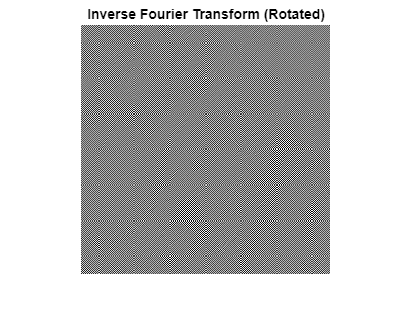


% Inverse Fourier Transform
I = ifft2(F, 256, 256);
figure;
imshow(real(I), []);
title('Inverse Fourier Transform (Rotated)');

**Observations**

- **Rotation**: Rotating the image changes the orientation of the frequency components in the Fourier transform. This can be observed in the shifted frequency spectrum.

- **Image Size**: Adjusting the image size ensures that the Fourier transform is computed correctly for the given dimensions.